load('C:\Users\Asus\Desktop\data_A')

    x=data_noise(1:1000,1:11);
    y=data_noise(1:1000,12);
    rng('default');
    cv = cvpartition(size(x,1),'HoldOut',0.3);
    idx = cv.test;
% Separate to training and test data
   x_train = x(~idx,:);
   x_test  = x(idx,:);
   y_train = y(~idx,:);
   y_test  = y(idx,:); 

Iteration: 1
Regressor Index: 5
Beta Values:
   10.3276

Iteration: 2
Regressor Index: 5  1
Beta Values:
   11.1681
   -0.2192

Iteration: 3
Regressor Index: 5  1  2
Beta Values:
   10.3969
   -0.5240
    0.7472

Iteration: 4
Regressor Index: 5   1   2  11
Beta Values:
    7.1833
   -1.0163
    2.2607
    3.9870

Iteration: 5
Regressor Index: 5   1   2  11   3
Beta Values:
    6.1897
   -0.8674
    1.3375
    4.3081
    1.4913

Iteration: 6
Regressor Index: 5   1   2  11   3   9
Beta Values:
    2.7332
   -0.6988
   -0.0104
    0.6928
    4.3280
    5.3563

Iteration: 7
Regressor Index: 5   1   2  11   3   9   4
Beta Values:
    2.3763
   -0.7040
    0.0532
    0.6249
    4.0534
    5.4857
    0.5114

Iteration: 8
Regressor Index: 5   1   2  11   3   9   4   6
Beta Values:
   -1.4580
   -0.7128
    0.1953
    0.8340
    3.1855
    4.8939
    3.0904
    2.3728

Iteration: 9
Regressor Index: 5   1   2  11   3   9   4   6  10
Beta Values:
   -8.5764
   -0.7205
    0.3394
   -1.7071
    2.

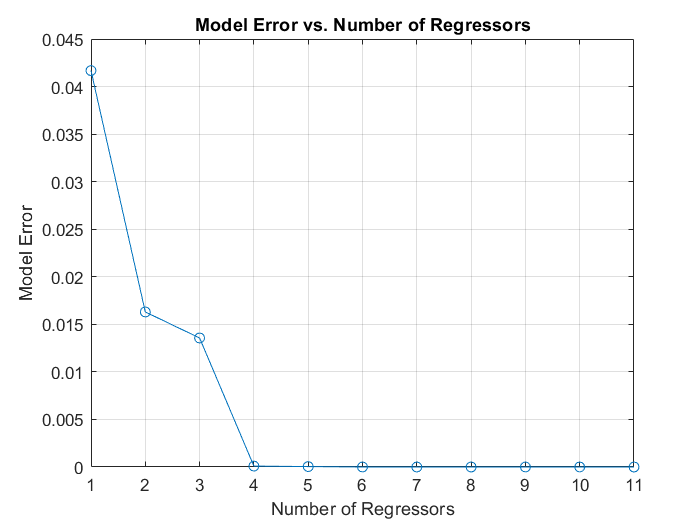

x_train = x(~idx, :);
x_test = x(idx, :);
y_train = y(~idx, :);
y_test = y(idx, :);
[bestModel, bestRegressorIdx] = forwardSelection(x_train, y_train); 

MSE_train=[];
MSE_test=[];
MAE_train=[];
MAE_test=[];
error_test=[];
error_train=[];
ghodrat_noise=[];
deghat_takhmin=[];
deghat_model=[];

   y_pred_train=x_train(:,1:8)*teta_hat;
   y_pred=x_test(:,1:8)*teta_hat;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test = MSE;
   
   MSE1 = mean((y_pred_train - y_train).^2);
   MSE_train = MSE1;
   
   errors =  y_test - y_pred;
   error_test=errors;
   
   errors1 =  y_train - y_pred_train;
   error_train=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test = MAE;

   MAE1 = mean((y_pred_train - y_train).^2);
   MAE_train = MAE1;
   
   
% subplot_rows = 3;
% subplot_cols = 4;
% 
%     % Generate the plot for the current i
% subplot(subplot_rows, subplot_cols, i);
u = x_test(:, 2);
cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-8);

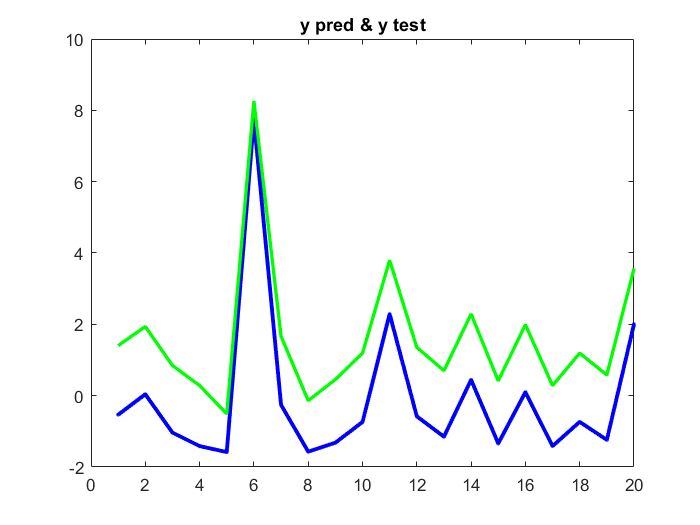

errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));






plot(y_pred(1:20,:),'.-b','linewidth',2.3);
hold on
plot(y_test(1:20,:),'-g','linewidth',2);
title("y pred & y test");
 hold off 

 
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
 

ghodrat_noise=errors.'*errors/(700-8);
deghat_takhmin=cov(teta_hat);
deghat_model=MSE;

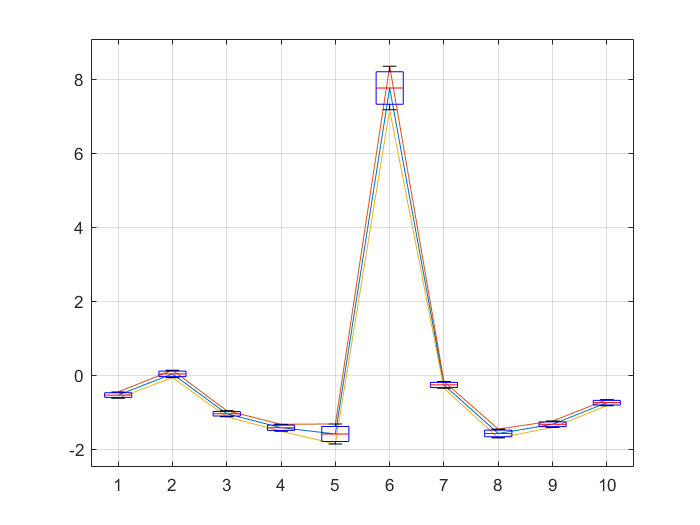

    
u1=1:1:10;
plot((y_pred(1:10,:)),'-');
hold on
plot((y_pred(1:10,:)+errbar(1:10,:)));
hold on
plot((y_pred(1:10,:)-errbar(1:10,:)));
grid

x=sort(u1).';
y=sort(y_pred(1:10,:)).';
data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.5);
hold off

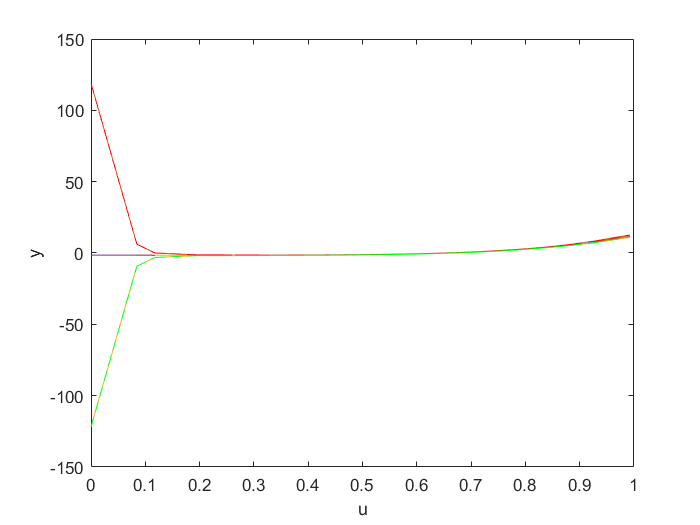

    upper_bound=y_pred + errbar;
    lower_bound=y_pred - errbar;
    
   [a_sorted, sort_idx] = sort(u);
b_sorted = y_pred(sort_idx);
c_sorted =upper_bound(sort_idx);
d_sorted =lower_bound(sort_idx);
% CI_low_sorted=CI_low(sort_idx)
% CI_high_sorted=CI_high(sort_idx)


plot(a_sorted, b_sorted, '-');
hold on;
plot(a_sorted, c_sorted, '-');
hold on
plot(a_sorted, d_sorted, '-');
hold on
% plot(a_sorted, CI_low_sorted, '-');
% hold on
% plot(a_sorted, CI_high_sorted, '-');
% hold on

for j = 1:length(a_sorted)-1
    x = [a_sorted(j), a_sorted(j+1)];
    y = [b_sorted(j), b_sorted(j+1)];
    plot(x, y);
    hold on
    xx = [a_sorted(j), a_sorted(j+1)];
    yy = [c_sorted(j), c_sorted(j+1)];
    plot(xx, yy, 'r--');
     hold on
    xxx = [a_sorted(j), a_sorted(j+1)];
    yyy = [d_sorted(j), d_sorted(j+1)];
    plot(xxx, yyy, 'g--');
%          hold on
%     xxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyy = [CI_low_sorted(j), CI_low_sorted(j+1)];
%     plot(xxxx, yyyy, 'g--');
%          hold on
%     xxxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyyy = [CI_high_sorted(j), CI_high_sorted(j+1)];
%     plot(xxxxx, yyyyy, 'g--');
end
    xlabel('u');
    ylabel('y');


    % Set subplot title

    hold off

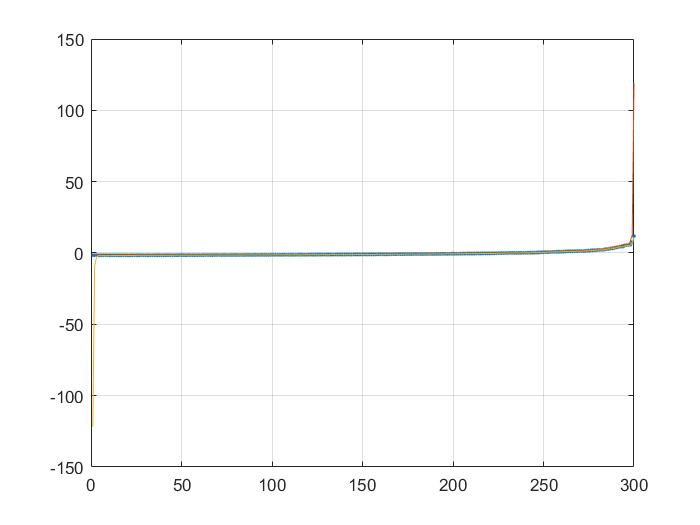

figure;
plot(sort(y_pred),'.');
hold on
plot(sort(y_pred+errbar));
hold on
plot(sort(y_pred-errbar));
grid

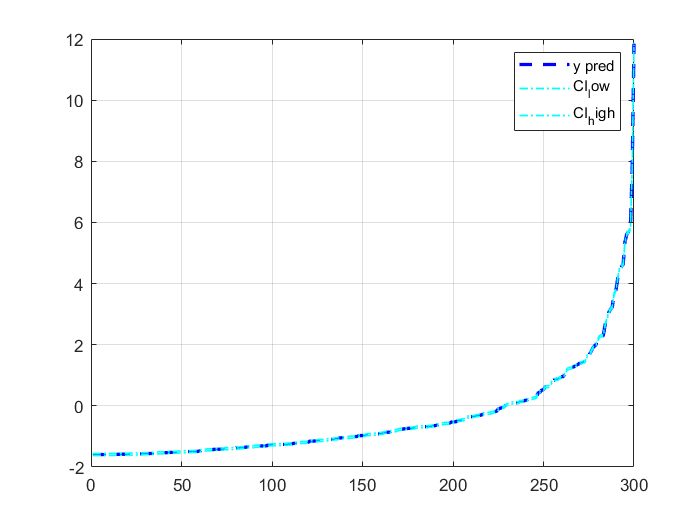

% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = y_pred - CI;
CI_high = y_pred + CI;

% Plot 
figure
plot(sort(y_pred), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y pred', 'CI_low', 'CI_high')
hold off

function [bestModel, bestRegressorIdx] = forwardSelection(x_train, y_train)
    % x_train: training input matrix with regressors as columns
    % y_train: training target variable
    
    numRegressors = size(x_train, 2);
    regressorIdx = 1:numRegressors;
    remainingIdx = regressorIdx;
    bestModelError = Inf;
    bestRegressorIdx = [];
    modelErrors = []; % Store model errors for plotting
    
    while ~isempty(remainingIdx)
        modelError = zeros(1, numel(remainingIdx));
        betaValues = cell(1, numel(remainingIdx)); % Store beta values
        
        for i = 1:numel(remainingIdx)
            candidateIdx = [bestRegressorIdx remainingIdx(i)];
            Xc = x_train(:, candidateIdx);
            beta = pinv(Xc) * y_train;
            yHat = Xc * beta;
            modelError(i) = mean((y_train - yHat).^2);
            betaValues{i} = beta;
        end
        
        [minError, bestIdx] = min(modelError);
        
        if minError < bestModelError
            bestModelError = minError;
            bestRegressorIdx = [bestRegressorIdx remainingIdx(bestIdx)];
            remainingIdx(bestIdx) = [];
            
            % Print beta values
            disp(['Iteration: ' num2str(numel(bestRegressorIdx))]);
            disp(['Regressor Index: ' num2str(bestRegressorIdx)]);
            disp('Beta Values:');
            disp(betaValues{bestIdx});
            
            % Store model error for plotting
            modelErrors = [modelErrors bestModelError];
        else
            break; % Exit the loop if no improvement
        end
    end
    
    % Plot the model error
    figure;
    plot(1:length(modelErrors), modelErrors, 'o-');
    xlabel('Number of Regressors');
    ylabel('Model Error');
    title('Model Error vs. Number of Regressors');
    grid on;
    
    bestModel = x_train(:, bestRegressorIdx);
end
